1.

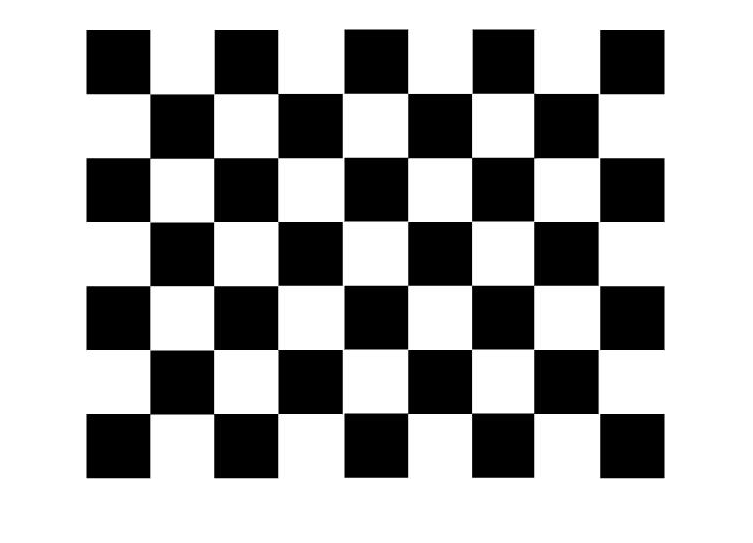

I=imread('checkerboard.jpg');
figure
imshow(I)

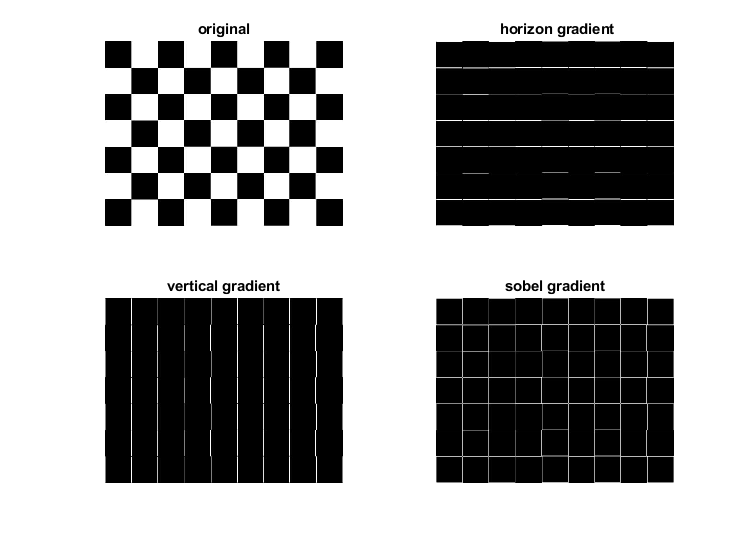

gray=rgb2gray(I);
gray = im2double(gray);
hx= fspecial('sobel');
hy=hx';
gradx = filter2(hx,gray,'same'); 
grady=filter2(hy,gray,'same'); 
gradx = abs(gradx);
grady=abs(grady);
grad=gradx+grady;
subplot(2,2,1);imshow(gray);title('original');
subplot(2,2,2);imshow(gradx,[]);title(' horizon gradient');
subplot(2,2,3);imshow(grady,[]);title('vertical gradient');
subplot(2,2,4);imshow(grad,[]);title('sobel gradient');

2.

Ix=gradx.^2

Ix =       0.78548      0.33686     0.013841   0.00038447   1.5379e-05   6.1515e-05   0.00075356    0.0022145   0.00055363            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0
       3.4991       10.929       15.073       15.379       15.502       15.657       15.564       15.719       15.812        15.75        15.75        15.75        15.75        15.75        15.75        15.75        15.75        15.75        15.75        15.75        15.75        15.75        15.75        15.75        15.75        15.75      

Iy=grady.^2

Iy =        3.9687       0.1477    0.0030142   0.00038447    0.0044444    0.0030142   0.00038447    0.0030142   0.00055363   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30   1.0934e-30
       1.3383       1.6646     0.035433   0.00055363    0.0015379    0.0018608    0.0015379    0.0012457    0.0015379   1.9768e-31   1.9768e-31   1.9768e-31   1.9768e-31   1.9768e-31   1.9768e-31   1.9768e-31   1.9768e-31   1.9768e-31   1.9768e-31   1.9768e-31   1.9768e-31   1.9768e-31   1.9768e-31   1.9768e-31   1.9768e-31   1.9768e-31   1.9

Ixy=gradx.^grady

Ixy =       0.78623      0.81133      0.88915       0.9258      0.69114      0.76631      0.93193      0.84552      0.91556            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0
       2.0637       4.6772       1.2909       1.0327       1.0552       1.0611       1.0553       1.0498       1.0556            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1            1     

3.

h=fspecial('gaussian',[3,1],1);
w=h.*h;
A=imfilter(Ix,w);
B=imfilter(Iy,w);
C=imfilter(Ixy,w);


4.5

k=0.04;
RMax=0;
height=size(gray,1);
width=size(gray,2);
R=zeros(height,width);
for h=1:height
    for w=1:width
         M=[A(h,w) C(h,w);C(h,w) B(h,w)]; 
        R(h,w)=det(M) - k*(trace(M))^2;   
        if(R(h,w)>RMax)
            RMax=R(h,w);                  
        end
    end
end


6.


a=0.01;
R_corner=(R>=(a*RMax)).*R;


7.

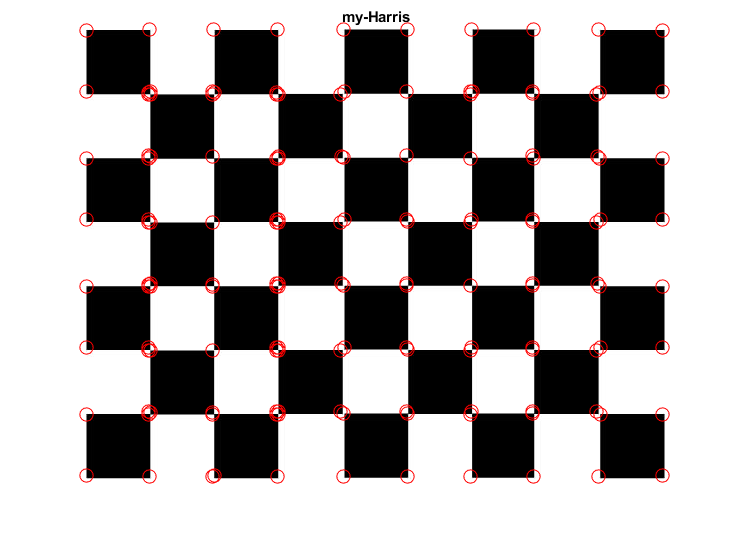

fun = @(x) max(x(:)); 
R_localMax = nlfilter(R,[3 3],fun); 
[row,col]=find(R_localMax(2:height-1,2:width-1)==R_corner(2:height-1,2:width-1));

figure
imshow(gray),title('my-Harris'),
hold on
plot(col,row, 'ro','MarkerSize',10),
hold off